# Activity 2

## Filter delay

Transmit and receive filters incur delays on the signal, which must be accounted for when the two bit sequences are compared.

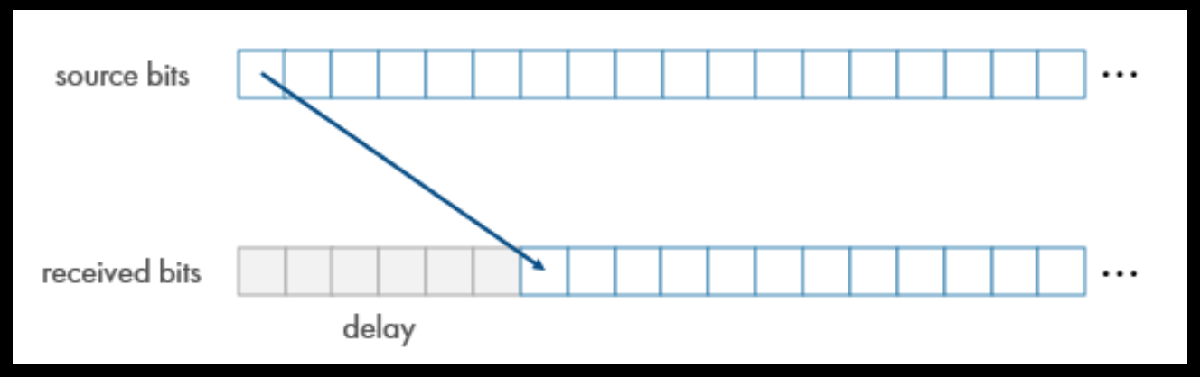

numBits = 20000;
modOrder = 16;  % for 16-QAM
bitsPerSymbol = log2(modOrder)  % modOrder = 2^bitsPerSymbol

bitsPerSymbol = 4

txFilt = comm.RaisedCosineTransmitFilter

txFilt =   comm.RaisedCosineTransmitFilter with properties:

                     Shape: 'Square root'
             RolloffFactor: 0.2000
       FilterSpanInSymbols: 10
    OutputSamplesPerSymbol: 8
                      Gain: 1


rxFilt = comm.RaisedCosineReceiveFilter

rxFilt =   comm.RaisedCosineReceiveFilter with properties:

                    Shape: 'Square root'
            RolloffFactor: 0.2000
      FilterSpanInSymbols: 10
    InputSamplesPerSymbol: 8
         DecimationFactor: 8
         DecimationOffset: 0
                     Gain: 1



srcBits = randi([0,1],numBits,1);
modOut = qammod(srcBits,modOrder,"InputType","bit","UnitAveragePower",true);
txFiltOut = txFilt(modOut);

SNR = 15;  % dB
chanOut = awgn(txFiltOut,SNR,"measured");

rxFiltOut = rxFilt(chanOut);
demodOut = qamdemod(rxFiltOut,modOrder,"OutputType","bit","UnitAveragePower",true);

**Background**

**For each filter, the delay is half the filter length, in symbols**. 

You can extract the filter length by accessing the `FilterSpanInSymbols` property. Then divide by 2 to get the delay.

`txFilt.FilterSpanInSymbols``/``2`

`rxFilt.FilterSpanInSymbols``/``2`

The total delay is the sum of the transmit and receive filter delays.

txfilt_delay = txFilt.FilterSpanInSymbols/2;
rxfilt_delay = rxFilt.FilterSpanInSymbols/2;
delayInSymbols = txfilt_delay+rxfilt_delay

delayInSymbols = 10

**However, to compare bits, you need to determine the delay in bits, not symbols.**

For 16-QAM, four bits are mapped to one symbol. This conversion factor has been stored in the variable `bitsPerSymbol`, defined in the script.

To convert the delay from symbols to bits, multiply the delay in symbols by `bitsPerSymbol`.

`delayInSymbols` `*` `bitsPerSymbol`

delayInBits = delayInSymbols * bitsPerSymbol

delayInBits = 40

# Extract Aligned Bits

Now that you know the delay, you're ready to compare bits. To compare the correct bits, you need to align matching bits from the source bit sequence and the received bit sequence.

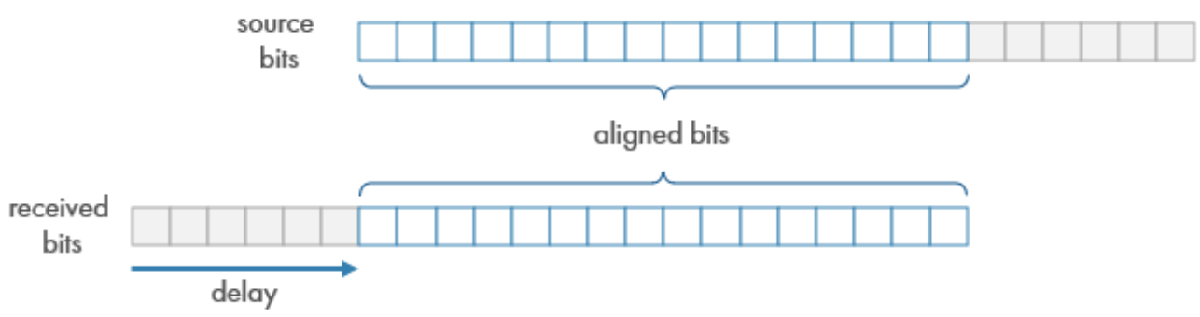**Background**

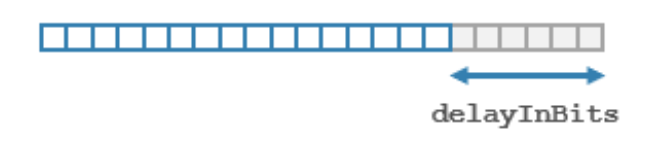

First, get the aligned bits from the source bit sequence by extracting all but the last `delayInBits` bits.

`srcBits(1:(end-delayInBits))`

srcAligned = srcBits(1:(end-delayInBits))

srcAligned =      1
     0
     0
     1
     0
     1
     0
     1
     1
     0


Next, get the aligned bits from the received bit sequence by extracting all but the first `delayInBits` bits.

`demodOut((delayInBits+1):``end``)`

demodAligned = demodOut((delayInBits+1):end);

Now you can compare the aligned bits and count the number of bit errors.

Remember you can use the `~=` operator to perform a bit-by-bit comparison to find nonmatching bits, and then use `nnz` to count the bit errors.

`nnz``(``bitSeq1` `~=` `bitSeq2``)`

numBitErrors = nnz(srcAligned ~= demodAligned)

numBitErrors = 0

The aligned bit stream is shorter than the original.

`numAlignedBits` `=` `length``(``srcAligned``)`

To calculate the bit error rate, you need to divide the number of bit errors by the number of aligned bits.

**Hint**

Divide `numBitErrors` by `length``(``srcAligned``)`. Alternately, use the fact that `delayInBits` bits have been dropped from the sequence, so you can divide `numBitErrors` by `(``numBits``-``delayInBits``)`.

BER = numBitErrors/length(srcAligned)

BER = 0

Remember you used a much lower signal-to-noise ratio when you added the filters, and the bit error rate is still very low. Try changing the value of `SNR` to see how it impacts the BER.

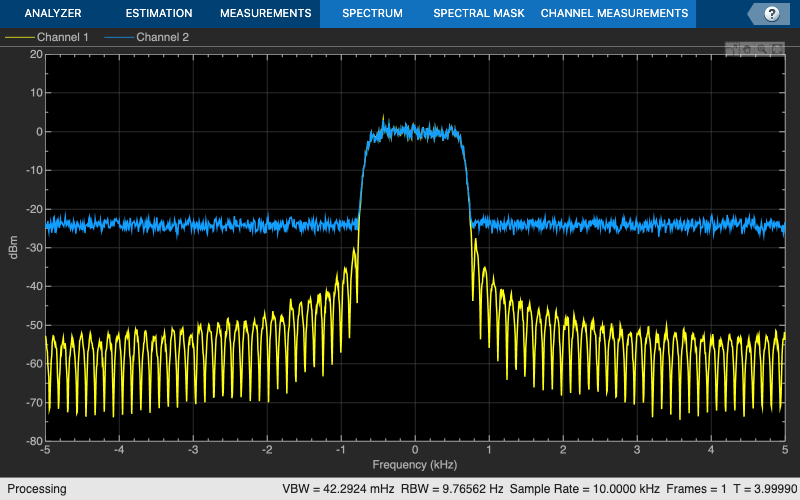

specAn = dsp.SpectrumAnalyzer("NumInputPorts",2, ...
    "SpectralAverages",50,...
    "ShowLegend",true);
specAn(txFiltOut,chanOut)